filt_data =     0.3499
    0.3616
    0.3732
    0.3845
    0.3955
    0.4059
    0.4156
    0.4245
    0.4326
    0.4398


beats = 1551×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


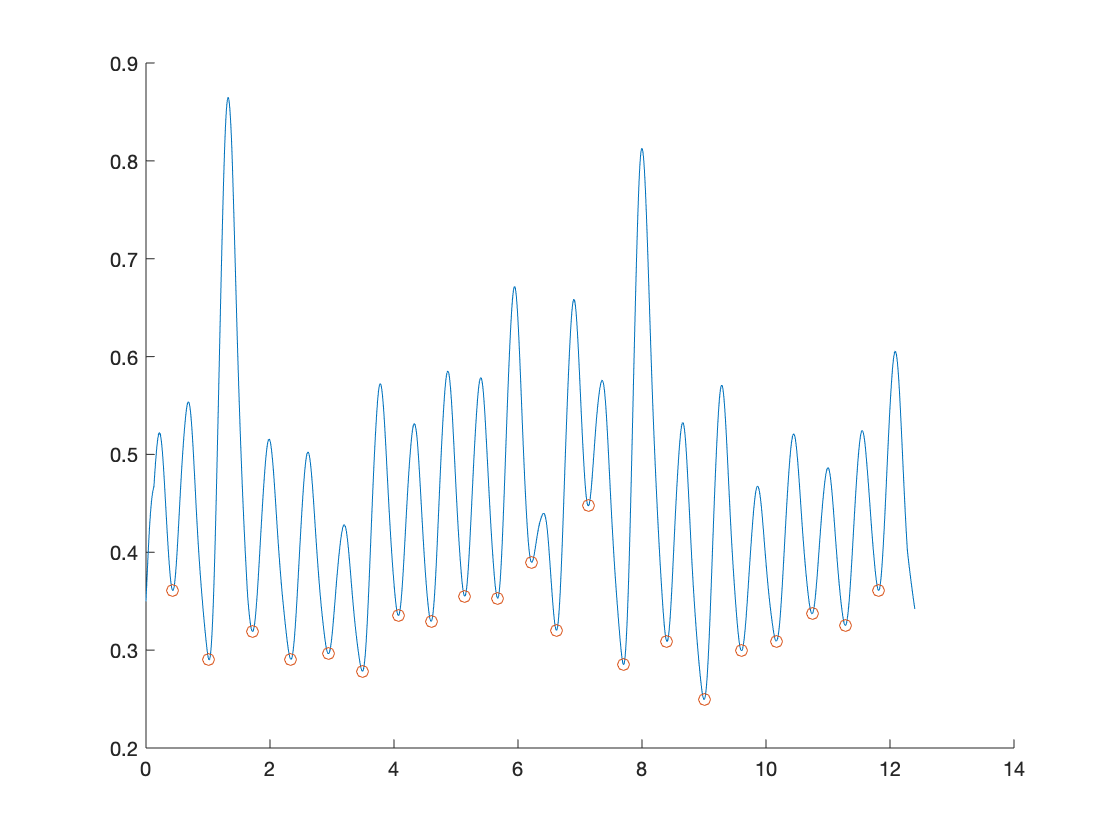

%FILTERING and SEGMENTING

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

filterAndSegment(opts);